%1 

function z = squareSum(x,y)
z = x.^2+y.^2;
end 

z = squareSum(2,3)

z = 13

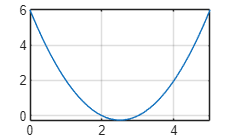


%2 
clc; clear; 
function z = poly1(x)
z = x.^2 -5.*x+6;
end

fplot(@poly1,[0,5])
grid on 



%3 
clc; clear; 
% 익명 함수 정의
f = @(x) x.^2 - 5.*x + 6;

% fzero 함수 사용 (fzero(함수핸들, 시작점))
root1 = fzero(f, 2)

root1 = 2

root2 = fzero(f, 3)

root2 = 3



function y = num3(x)
    % 이 파일 이름은 반드시 num3.m 이어야 합니다!
    y = x.^2 - 5.*x + 6;
end

% 함수 이름(num3)에 @를 붙여서 넘겨줍니다.
root1 = fzero(@num3, 2)

root1 = 2

root2 = fzero(@num3, 3)

root2 = 3




%4 
clc; clear;
f = @(x) (sqrt(x.^2+1));

f([0 1 2])

ans =     1.0000    1.4142    2.2361


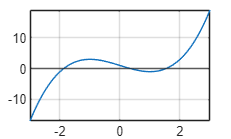



%5 
clc; clear ; 

f = @(x) x.^3 - 3*x + 1;
fplot(f,[-3 3])
grid on
yline(0)


%0점은 3개 ... 

x1 = fzero(f,0)

x1 = 0.3473

x2 = fzero(f,-2)

x2 = -1.8794

x3 = fzero(f,2)

x3 = 1.5321



%chp 3 exercises 

%T3.2-1 

function [A,V] = cube(L)
 A = L^2;
 V = L^3; 
end

[A,V]= cube(10)

A = 100

V = 1000


%T3.2-2 
 
clc; clear; 
function V = cone(h,r)
 V = pi*(r^2)*(h/3);
end 

V = cone(30,5)

V = 785.3982


%T3.2-3 

f = @(x) (exp(-0.2.*x).*sin(x+2))

f = 다음 값을 갖는 function_handle:
    @(x)(exp(-0.2.*x).*sin(x+2))


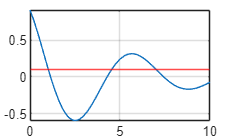


fplot(f,[0,10])
grid on
yline(0.1,'-r')


root1 = fzero(f,2)

root1 = 1.1416

root2 = fzero(f,5)

root2 = 4.2832

root3 = fzero(f,7)

root3 = 7.4248



%T3.2-4 
clc; clear; 

f = @(x) 1 + exp(-0.2.*x).*sin(x+2);
fp = @(x) exp(-0.2.*x).*(cos(x+2) - 0.2.*sin(x+2));
x1 = fzero(fp, [2,3])

x1 = 2.5150

x2 = fzero(fp,[8, 9.5])

x2 = 8.7982

y1 = f(x1)

y1 = 0.4070

y2 = f(x2)

y2 = 0.8312



%T3. 2-5 
clc; clear; 

% 깊이 d, 각도 theta , 바닥폭  b 

A = 200;
P = @(x) A./x(1) - x(1)*cot(x(2)) + 2*x(1)*csc(x(2));
% x(1) = d, x(2) = theta (radian)
x0 = [10, pi/3];
x = fminsearch(P, x0)

x =    10.7457    1.0472


d = x(1);
theta_rad = x(2);
theta_deg = theta_rad*180/pi;
[d, theta_deg]

ans =    10.7457   60.0000



%실예제 1 

function z = squareVec(x)
 z = x.^2 ;
end 

for i = [2:2:8]
    z = squareVec(i)
end 



%2 
clc; clear; 
function z = meanVec(x) 
z = mean(x);
end 
x = 0;
for i = [3,5,7,9]
    x = x + i;
end
z = meanVec(x)

%3
clc; clear; 

function y = linearTransform(x)
y = 2.*x + 1; 
end 

for i = 1:4
    y = linearTransform(i);
end


%자유 낙하 물체 
g = 9.81; % 중력 가속도 (m/s^2)
start = 0; 
incr = 0.1; 
finish = 2;
t = start:incr:finish;
% 낙하거리를 계산한다.
d = 1/2*g*t.^2;
% 결과를 그래프로 그린다.
loglog(t,d)
title('자유낙하 거리 그래프')
xlabel('시간, s')
ylabel('낙하거리, m')
% 총 낙하거리를 계산한다.
final_distance = max(d)

%사용자 제어 입출력 

%1
clc; clear; 

a = input('수 입력: ');
b = input('>: ');
c = a+b

%2 
r = input('반지름: ');

v = pi*(r^2)

%3 
s = input('>:','s');
fprintf('%s is hello!\n',s)

%4 
n = input('행렬입력[]: ');
disp(n)

%5 
clc; clear;
c = input('섭씨: ');
f = (c * 9/5) + 32; % 섭씨를 화씨로 변환
fprintf('화씨: %.2f\n', f)








